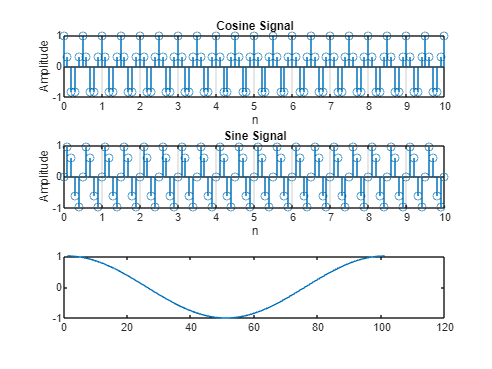

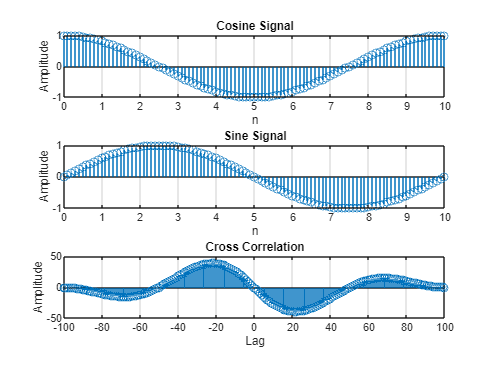

% Generate a discrete time sinusoidal signal cos(2πf0n) with any frequency
f0 =  0.1; % Frequency of the sinusoidal signal

n = 0:0.1:10; % Predefined time axis for 10 time periods
x1 = cos(2*pi*f0*n); % Generate the cosine signal
% Generate another discrete time sinusoidal signal sin(2πf0n) with the same frequency and time axis
x2 = sin(2*pi*f0*n); % Generate the sine signal

% Find the cross correlation of the two signals
cross_corr = xcorr(x1, x2);

% Plot all of the signals with proper labeling
figure;

% Plot the first sinusoidal signal

stem(n, x1);
xlabel('n');
ylabel('Amplitude');
title('Cosine Signal');
grid on;

% Plot the second sinusoidal signal

stem(n, x2);
xlabel('n');
ylabel('Amplitude');
title('Sine Signal');
grid on;

% Plot the cross correlation of the two signals
L = length(cross_corr);
lag = -(L-1)/2:(L-1)/2;

stem(lag, cross_corr);
xlabel('Lag');
ylabel('Amplitude');
title('Cross Correlation');
grid on;

